
beta = .001;
alpha = .1;
gamma = 0.1;
R0 = beta / alpha

R0 = 0.0100

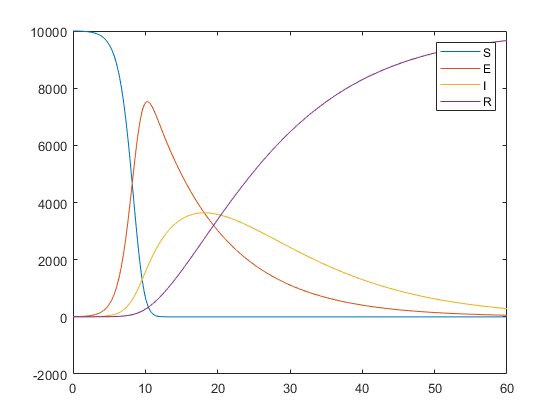

tspan = [0 60];
y0 = [10000 10 0 0];
[t,y] = ode45(@(t,y) odefcn(t,y,beta,alpha,gamma), tspan, y0);
plot(t,y)
legend({'S','E','I','R'})

beta = .001;
alpha = .1;
tspan = [0 60];
R0 = beta / alpha

R0 = 0.0100

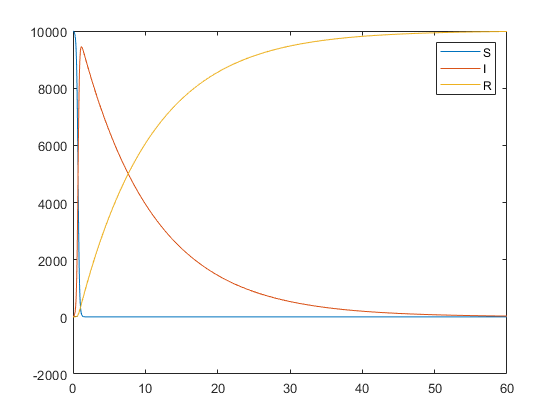

y0 = [10000 10 0];
[t,y] = ode45(@(t,y) odesir(t,y,beta,alpha), tspan, y0);
plot(t,y)
legend({'S','I','R'})

function dx = odefcn(t,y,beta,alpha,gamma)
  dx = zeros(4,1);
  dx(1) = -beta*y(1)*y(3);
  dx(2) = beta*y(1)*y(3)-gamma*y(2);
  dx(3) = gamma*y(2)-alpha*y(3);
  dx(4) = alpha*y(3);
end

function dx = odesir(t,y,beta,alpha)
  dx = zeros(3,1);
  dx(1) = -beta*y(1)*y(2);
  dx(2) = beta*y(1)*y(2) - alpha*y(2);
  dx(3) = alpha*y(2);
end